# Operaciones matriciales

## Multiplicación y potencia

### Ejercicio 1

Con un calorímetro de bomba se realizó una serie de experimentos. En cada experimento se usó una cantidad diferente de agua. Calcule la capacidad calorífica total para el calorímetro en cada uno de los experimentos.

**Figura 1.** Propiedades términas de un calorímetro de bomba.

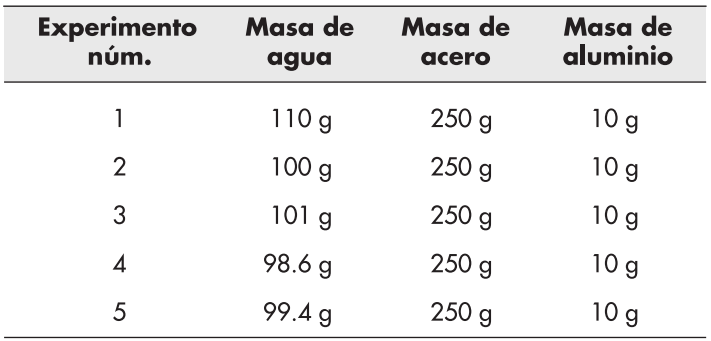

**Figura 2.** Capacidad calorímetra.

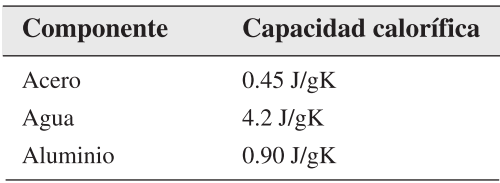

*Tablas tomadas de MATLAB para ingenieros de Holly Moore.*

*Ejercicio tomado de Moore, 2007.*

### Solución

experimentos=[110 250 10 
              100 250 10
              101 250 10 
              98.6 250 10
              99.4 250 10]

experimentos =   110.0000  250.0000   10.0000
  100.0000  250.0000   10.0000
  101.0000  250.0000   10.0000
   98.6000  250.0000   10.0000
   99.4000  250.0000   10.0000


capCalor=[4.2 0.45 0.90]'

capCalor =     4.2000
    0.4500
    0.9000


Total=experimentos*capCalor

Total =   583.5000
  541.5000
  545.7000
  535.6200
  538.9800


### Ejercicio 2

El peso molecular ($\textrm{MW}$) de cualquier compuesto es la suma de los productos del número de átomos de cada elemento ($Z$) y el peso atómico ($\textrm{AW}$) de cada elemento presente en el compuesto, o


$$\textrm{MW}=\sum_{i=1}^n {\textrm{AW}}_i \cdot Z_i$$


En la tabla se mencionan las composiciones de los primeros cinco alcoholes de cadena recta. Use los pesos atómicos del carbono, hidrógeno y oxígeno (12, 1 y 16,  respectivamente) y la multiplicación matricial para determinar el peso molecular (más  correctamente llamada masa molar) de cada alcohol.

**Figura 3.** Composición de alcoholes.

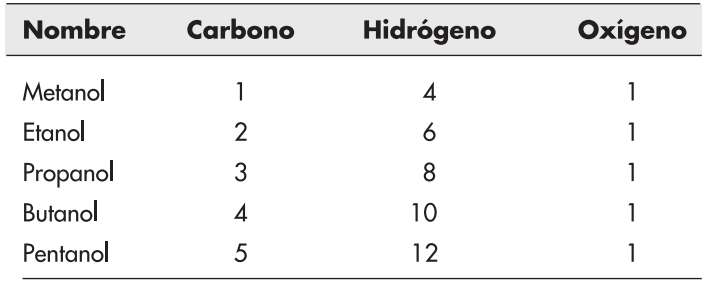

*Tomado de MATLAB para ingenieros de Holly Moore.*

*Ejercicio tomado de Moore, 2007.*

### Solución

alcoholes=[1 4 1
           2 6 1
           3 8 1
           4 10 1
           5 12 1]

alcoholes =      1     4     1
     2     6     1
     3     8     1
     4    10     1
     5    12     1


pesoAtom=[12 1 60]'

pesoAtom =     12
     1
    60


masaMolar=alcoholes*pesoAtom

masaMolar =     76
    90
   104
   118
   132


## División izquierda

### Ejercicio 1

Resolver el siguiente sistema de ecuaciones lineales.


$$\begin{array}{l}
2x_1 +2x_2 -3x_3 +5x_4 +8x_5 =-2\\
9x_1 -3x_2 -3x_3 -8x_4 +2x_5 =1\\
7x_1 +5x_2 -7x_3 -3x_4 +9x_5 =-15\\
3x_1 -2x_2 +2x_3 -5x_4 +7x_5 =0\\
2x_1 -4x_2 +9x_3 -9x_4 +6x_5 =7
\end{array}$$


### Solución

A=[2 2 -3 5 8
   9 -3 -3 -8 2
   7 5 -7 -3 9
   3 -2 2 -5 7
   2 -4 9 -9 6]

A =      2     2    -3     5     8
     9    -3    -3    -8     2
     7     5    -7    -3     9
     3    -2     2    -5     7
     2    -4     9    -9     6


b=[2 1 -15 0 7]'

b =      2
     1
   -15
     0
     7


x=A\b

x =     2.2456
   -1.2443
    2.0316
    1.9861
   -0.4797


### Ejercicio 2

Suponga que una economía consiste en los sectores de carbón, electricidad y acero, y que el rendimiento de cada sector se distribuye entre los diferentes  sectores como en la tabla, donde las entradas de una columna representan fracciones de la producción total de un sector. La segunda columna de la tabla, por ejemplo, muestra que la producción total de electricidad se divide como sigue: un 40% de carbón, un 50% de acero, y el restante 10% de electricidad. (El sector eléctrico trata este 10% como un gasto en que incurre para hacer funcionar su negocio.) Ya que debe tomarse en cuenta la producción total, las  fracciones decimales de cada columna deben sumar 1. Los precios (es decir, valores en moneda) de la producción total de los sectores de carbón, electricidad y acero se denotarán como $p_C$, $p_E$ y $p_S$, respectivamente. Si es posible, encuentre los precios de equilibrio que permiten a los ingresos de cada sector  igualar sus gastos.

**Figura 4.** Una economía sencilla.

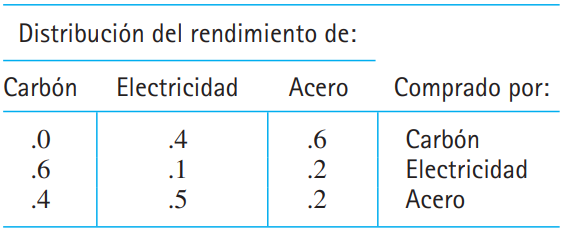

*Tomado de Álgebra lineal y sus aplicaciones de David C. Lay.*

*Ejercicio tomado de Lay, 2007.*

**Recomendación:** Empezar generando manualmente las ecuaciones de cada columna. Por ejemplo, la primera columna responde a la ecuación $p_C =\ldotp 0p_C +\ldotp 6p_E +\ldotp 4p_S$. Luego reordenar las ecuaciones y variables para generar el sistema matricial y resolverlo.

**Nota:** Este ejercicio corresponde a las aplicaciones de sistemas de ecuaciones lineales en economía, específicamente al *modelo de intercambio sencillo*, desarrollado por Leontief.


$$p_C =\ldotp 0p_C +\ldotp 6p_E +\ldotp 4p_S$$



$$p_E =\ldotp 4p_C +\ldotp 1p_E +\ldotp 5p_S$$



$$P_S =\ldotp 6p_C +\ldotp 2p_E +\ldotp 2p_S$$


### Solución

Z=[0 .6 .4
   .4 .1 .5
   .6 .2 .2]

Z =          0    0.6000    0.4000
    0.4000    0.1000    0.5000
    0.6000    0.2000    0.2000


b=[1 1 1]'

b =      1
     1
     1


sol=Z\b

sol =     1.0000
    1.0000
    1.0000
